clear
close all
clc

Generate virtual robot at (0,0,0)

tic;
resolution = 1000;
reach = 100;
% robot = generateVirtualRobot(100);
% [H1Mean,H2Mean,H1,H2,jnt1Lim,jnt2Lim] = generateWorkspaceMean(robot,resolution);
[H1Mean,H2Mean,H1,H2,jnt1Lim,jnt2Lim] = generateWorkspace(resolution,reach);
stage1Time = toc;

Load CT images and binary masks from 3D slicer exports

tic;
rawImage = niftiread("Panoramix-cropped.nii");
mask = niftiread("Panoramix-cropped segmentation-L4 vertebra-label.nii");

Resample the 3D volume to equalize the voxel sizes and find the reference point (centroid)

[resampledMask,resampledVol] = resample(rawImage,mask,[0.7421875 0.7421875],1.5);
resampledVol = double(resampledMask).*double(resampledVol);
[centroidLoc,centroidX,centroidY,centroidZ] = centroid(resampledMask);

Surgeon specify the insertion point (WIP)

insertionPoint = [190 120 161];
insertionTransform = se3(trvec2tform(insertionPoint));

Shift the starting point from the centroid to inside the spinal canal for spinal canal localization

[shiftedX, shiftedY] = centroidShift(centroidX,centroidY,centroidZ,resampledMask);

Using floodfill to define the area of the spinal canal at the level of the centroid

[spinalCanal,stackX,stackY] = floodfill(resampledMask(:,:,centroidZ),shiftedX,shiftedY);
canalMaxY = max(stackY);
canalMinY = min(stackY);
[canalCenter,canalCenterX,canalCenterY] = center(spinalCanal);

Cut out the pedicle from the rest of the volume

pedicle = cutPedicle(resampledVol,canalMaxY,canalMinY,15,1);
pedicleMask = cutPedicle(resampledMask,canalMaxY,canalMinY,15,1);

Cut out only the pedicle on the side that we are interested in

pedicleROI = pedicleROICut(pedicle,insertionPoint(1),centroidX);
pedicleROIMask = pedicleROICut(pedicleMask,insertionPoint(1),centroidX);

Run PCA to get the pricipal axis of the pedicle

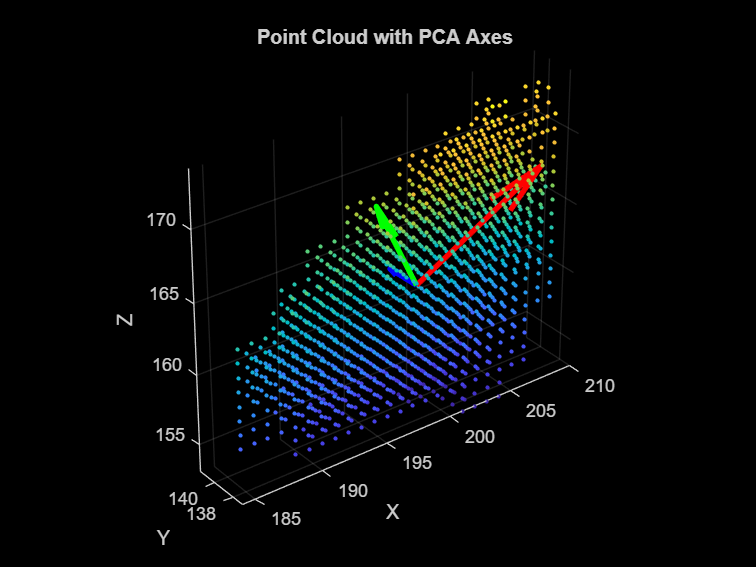

pediclePtCloud = voxelToPointCloud(pedicleROIMask);
[pedicleCoeff,~,pedicleLatent] = pca(pediclePtCloud.Location);
pedicleCenterPoint = mean(pediclePtCloud.Location,1);
scalingFactor = sqrt(pedicleLatent)*2;
pcaVectors = pedicleCoeff .* scalingFactor';
plotPCAWithPointCloud(pediclePtCloud)

Get the surface voxel of the vertebra

vertebraSurf = extractSurfaceVoxels(resampledMask);

Convert the surface voxel into the pointcloud of the surface

ptCloud = voxelToPointCloud(vertebraSurf);
stage2Time = toc;

## Search

tic;
HTemp = H1Mean*H2Mean*insertionTransform;
costTemp1 = zeros(resolution,1);
costTemp2 = zeros(resolution,1);

Search H1

for i = 1:resolution
    costTemp1(i) = costTotal(insertionPoint,insertionTransform,insertionTransform*se3(H1(:,:,i))*H2Mean,ptCloud,pcaVectors(:,3)',pedicleCenterPoint);
end

[~,ITemp1] = min(costTemp1);
H1Final = se3(H1(:,:,ITemp1));
jnt1Final = jnt1Lim(ITemp1);

Search H2

for i = 1:resolution
    costTemp2(i) = costTotal(insertionPoint,insertionTransform,insertionTransform*H1Final*se3(H2(:,:,i)),ptCloud,pcaVectors(:,3)',pedicleCenterPoint);
end

[costFinal,ITemp2] = min(costTemp2);
H2Final = se3(H2(:,:,ITemp2));
jnt2Final = jnt2Lim(ITemp2);

Determine final trajectory

finalTraj = genTraj(insertionTransform,insertionTransform*H1Final*H2Final);
stage3Time = toc;

Convert final transform to pedicle screw angle

trajProjectedYZ = [0,finalTraj(2),finalTraj(3)];
pitchAngle = rad2deg(atan2(norm(cross([0 1 0],trajProjectedYZ)),dot([0 1 0],trajProjectedYZ)));
trajProjectedXY = [finalTraj(1),finalTraj(2),0];
yawAngle = rad2deg(atan2(norm(cross([0 1 0],trajProjectedXY)),dot([0 1 0],trajProjectedXY)));

Plot final trajectory

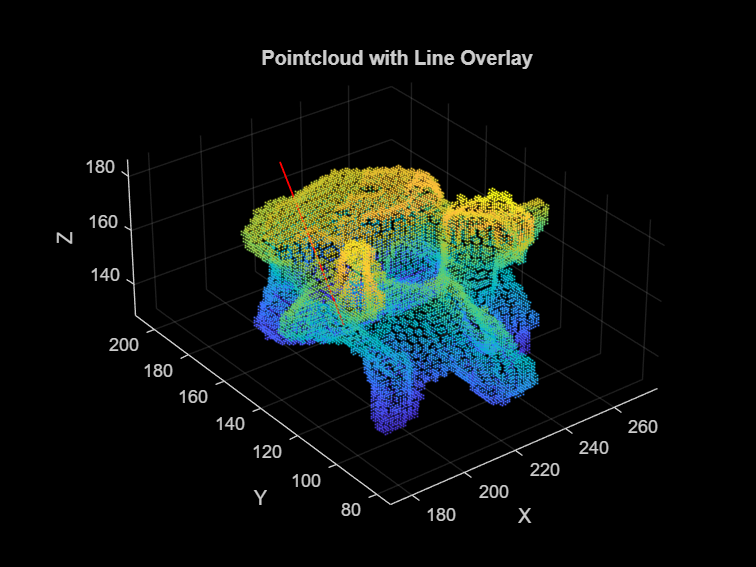

% Define the line (vector)
lineOrigin = insertionPoint;  % Define start point of the line
lineDirection = finalTraj; % Direction vector
lineLength = reach;            % Length of the line

% Compute line endpoints
lineEnd = lineOrigin + lineDirection * lineLength;

% Plot the pointcloud
figure;
pcshow(ptCloud)
hold on;

% Plot the line using plot3
plot3([lineOrigin(1), lineEnd(1)], ...
      [lineOrigin(2), lineEnd(2)], ...
      [lineOrigin(3), lineEnd(3)], 'r-', 'LineWidth', 1);

% Add labels and formatting
title('Pointcloud with Line Overlay');
xlabel('X'); ylabel('Y'); zlabel('Z');
axis equal;
grid on;
view(3);  % Set 3D view
camlight; lighting phong;
hold off;

totalTime = stage1Time + stage2Time + stage3Time;
disp("Total Time: " + totalTime + " s")

Total Time: 5.732 s


disp("Stage 1 (Workspace Generation) Time: " + stage1Time + "s")

Stage 1 (Workspace Generation) Time: 0.065927s


disp("Stage 2 (Image and Volume Processing) Time: " + stage2Time + "s")

Stage 2 (Image and Volume Processing) Time: 4.9301s


disp("Stage 3 (Search) Time: " + stage3Time + "s")

Stage 3 (Search) Time: 0.73601s


disp("Pitch: " + pitchAngle + "deg")

Pitch: 0deg


disp("Yaw: " + yawAngle + "deg")

Yaw: 24.7748deg


volumeSize = [441 321 435];
medRef = medicalref3d(volumeSize);
medRef.PatientCoordinateSystem = "RAS+";
medVol = medicalVolume(resampledVol,medRef);
render = volshow(medVol,Alphamap="linear",RenderingStyle="MaximumIntensityProjection");
% medVol = medicalVolume(resampledMask,medRef);
% render = volshow(medVol,Alphamap="linear",RenderingStyle="Isosurface");
%render.Colormap = parula;
viewer = render.Parent;
viewer.BackgroundColor = [0 0 0];
viewer.BackgroundGradient = "on";
viewer.GradientColor = "w";